# Histogram of the image

`part1: Get image histogram`

## read the image

image = imread('image.jpg');

## get the histogram of the image using imhist

hist = imhist(image);

## get the histogram manually

manualHist = zeros(256, 1);

for i = 1 : 256
    manualHist(i) = sum(sum(image(:) == i - 1));
end

## verify that manualHist equals hist

if(sum(manualHist == hist) == 256)
    disp('Manual hist gives the same result as the built in function')
end

Manual hist gives the same result as the built in function


`part2: perform histogram equalization`

figure
J = histeq(image)

J = 682×1024×3 uint8 array
J(:,:,1) =

    65    65    65    65    65    65    65    65    65    65    65    65    65    65    65    65    69    69    65    65    69    69    69    65    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    73    73    73    69    65    65    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    73    73    73    69    69    69    69    69    65    65    69    69    69    69    69    69    69    69    69    73    73    73    77    77    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    73    69    69    73    77    77    73    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    69    73    73    73    73    77    77    77    81 

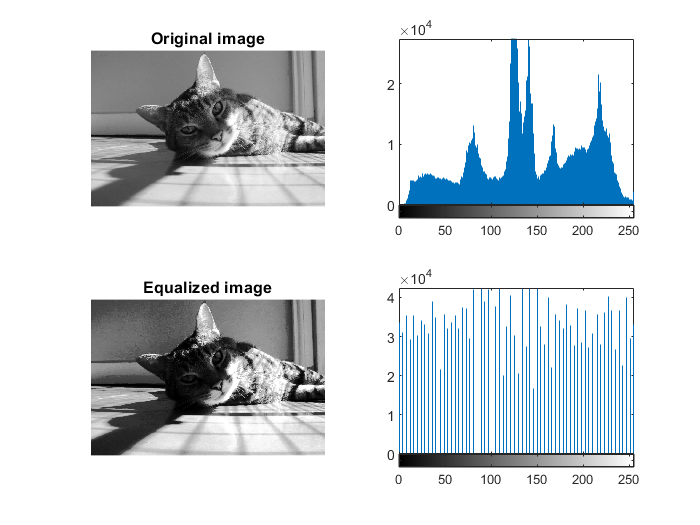


subplot(2, 2, 1)
imshow(image)
title('Original image')

subplot(2, 2, 3)
imshow(J)
title('Equalized image')

subplot(2, 2, 2)
imhist(image)

subplot(2, 2, 4)
imhist(J)

## do histogram qualization manually

% calculate cdf 
% can use cumsum()
cdf = zeros(256, 1);
for i = 1: 256
    cdf(i) = sum(hist(1:i))
end

cdf =     21
     0
     0
     0
     0
     0
     0
     0
     0
     0


cdf =     21
    30
     0
     0
     0
     0
     0
     0
     0
     0


cdf =     21
    30
    48
     0
     0
     0
     0
     0
     0
     0


cdf =     21
    30
    48
    78
     0
     0
     0
     0
     0
     0


cdf =     21
    30
    48
    78
   123
     0
     0
     0
     0
     0


cdf =     21
    30
    48
    78
   123
   198
     0
     0
     0
     0


cdf =     21
    30
    48
    78
   123
   198
   366
     0
     0
     0


cdf =     21
    30
    48
    78
   123
   198
   366
   675
     0
     0


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
           0


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf =           21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


cdf = 256×1
          21
          30
          48
          78
         123
         198
         366
         675
        1377
        2403


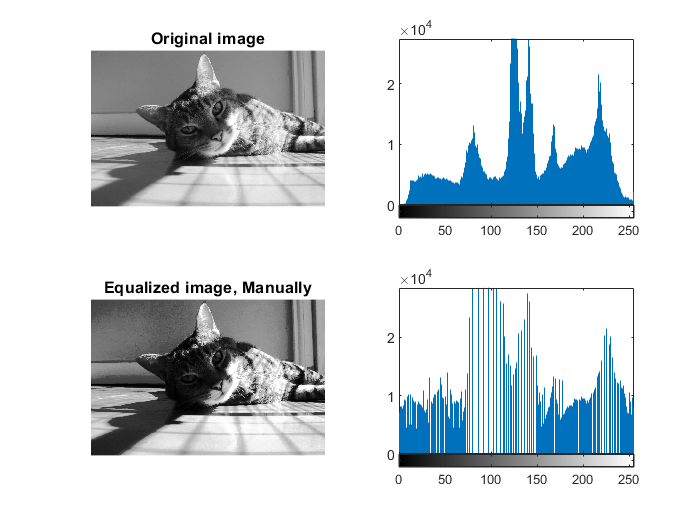


% normalize cdf
maxCount = max(hist);
maxCDF = max(cdf);

cdfNormalized = cdf / numel(image);

% create mapping function or lookup table
LUT = round(cdfNormalized * 255);

% apply look up table to the image
newImage = uint8(LUT(double(image) + 1));

figure

subplot(2, 2, 1)
imshow(image)
title('Original image')

subplot(2, 2, 3)
imshow(newImage)
title('Equalized image, Manually')

subplot(2, 2, 2)
imhist(image)

subplot(2, 2, 4)
imhist(newImage)

`part3: histogram matching`

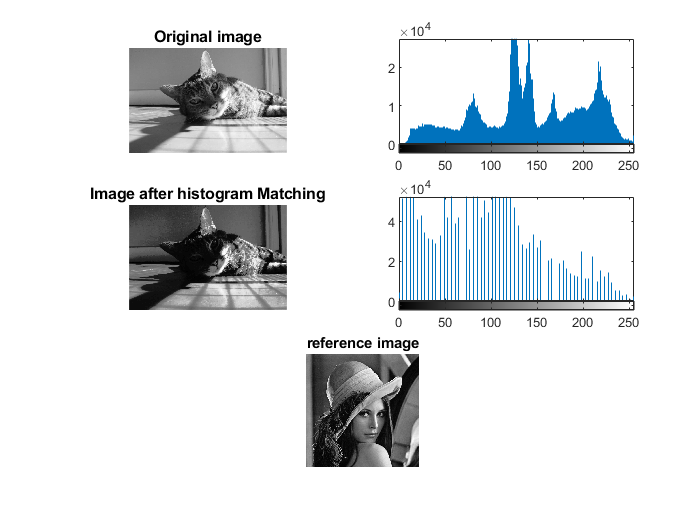

ref = imread('ref.png');
imgMatch = imhistmatch(image, ref);

figure

subplot(3, 2, 1)
imshow(image)
title('Original image')

subplot(3, 2, 2)
imhist(image)

subplot(3, 2, 3)
imshow(imgMatch)
title('Image after histogram Matching')

subplot(3, 2, 4)
imhist(imgMatch)

subplot(3, 2, [5, 6])
imshow(ref)
title('reference image')

## Histogram matching, manually

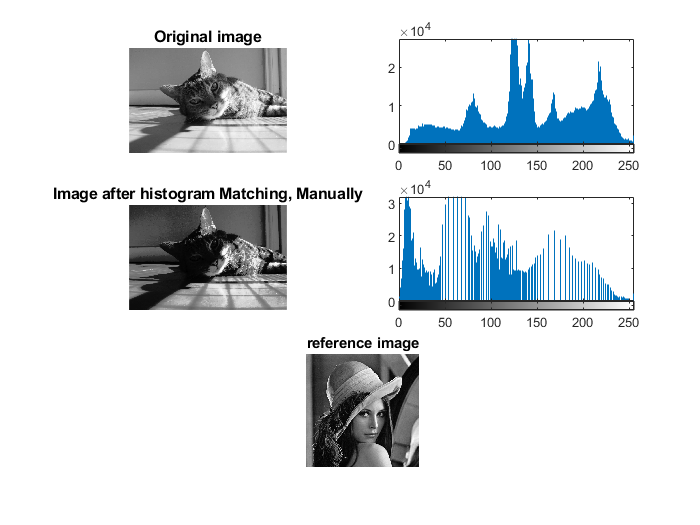

% get histogram of input image and reference
histInput = imhist(image);
histRef = imhist(ref);

% get cdf
cdfInput = cumsum(histInput);
cdfRef = cumsum(histRef);

% normalize cdf
cdfInputNorm = cdfInput / numel(image);
cdfRefNorm = cdfRef / numel(ref);

% create a mapping function
matchLUT = zeros(256, 1);
for i = 1: 256
    [~, index] = min(abs(cdfRefNorm - cdfInputNorm(i)));
    matchLUT(i) = index - 1;
end

% apply LUT
imgHistMatch = uint8(matchLUT(double(image) + 1));

% plot
figure

subplot(3, 2, 1)
imshow(image)
title('Original image')

subplot(3, 2, 2)
imhist(image)

subplot(3, 2, 3)
imshow(imgHistMatch)
title('Image after histogram Matching, Manually')

subplot(3, 2, 4)
imhist(imgHistMatch)

subplot(3, 2, [5, 6])
imshow(ref)
title('reference image')